ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Class'


cs

cs =   pr730Class with properties:

          ver: '6/15/2022'
      comPort: [1×1 rs232Class]
    connected: 1
     settings: '00000,FP-730-4,None,None,None,2 deg,Metric,Adaptive,500 msec,4xFast,1 cycles,2 deg,No Smart Dark,Standard Sensitivity,No Sync,20.00 Hz,5 nm'


ols

ols =   OL490Sim with properties:

          col_spec: [1024×401 double]
          speC_max: [1×1 SpectrumClass]
          speC_min: [1×1 SpectrumClass]
         reflC_min: [1×1 SpectrumClass]
         classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim'
     inputdatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/spike_0615.mat'
    outputdatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_0615.mat'


## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

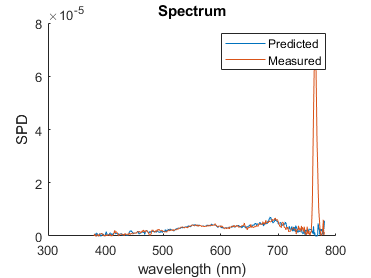

col_range  = [1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

ol.setColumn1024Gamma(vec)
mea = cs.measure;
mea.plot

legend('Predicted','Measured')

sc = 1;
spec_z24x = xlsread('hpz24x_rgb.csv');
spec_z24x = spec_z24x(21:end,:)'*sc;
vec_r = ls.spd2vec(spec_z24x(1,:));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 31.322112 
stopped after 101 iteration

ans = 'Done solving M * A = B with R...'

Elapsed time is 201.655638 seconds.


vec_g = ls.spd2vec(spec_z24x(2,:));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 37.995038 
stopped after 101 iteration

ans = 'Done solving M * A = B with R...'

Elapsed time is 203.899279 seconds.


vec_b = ls.spd2vec(spec_z24x(3,:));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 10.607193 
stopped after 101 iteration

ans = 'Done solving M * A = B with R...'

Elapsed time is 201.629167 seconds.


            nec = NECPA271Sim;
            
            vec_r = ls.spd2vec(nec.spec_r);

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.

iterations 73
function evaluations 76
segments exp

ans = 'Done solving M * A = B with R...'

Elapsed time is 151.213885 seconds.


            vec_g = ls.spd2vec(nec.spec_g);

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 0.612019 
stopped after 101 iterations

ans = 'Done solving M * A = B with R...'

Elapsed time is 205.310853 seconds.


            vec_b = ls.spd2vec(nec.spec_b);

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 0.148685 
stopped after 101 iterations

ans = 'Done solving M * A = B with R...'

Elapsed time is 201.802482 seconds.


            rs = RiftSim;
            
            vec_r = ls.spd2vec(rs.output([255 0 0]));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 1.195300 
stopped after 101 iterations

ans = 'Done solving M * A = B with R...'

Elapsed time is 202.141307 seconds.


            vec_g = ls.spd2vec(rs.output([0 255 0]));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 4.718821 
stopped after 101 iterations

ans = 'Done solving M * A = B with R...'

Elapsed time is 201.883391 seconds.


            vec_b = ls.spd2vec(rs.output([0 0 255]));

ans = 'Solving M * A = B with R...'

ans = 0

ans = 0

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
N = 1024, M = 5 machine precision = 2.22045e-16
The initial X is infeasible.  Restart with its projection.
final  value 3.481751 
stopped after 101 iterations

ans = 'Done solving M * A = B with R...'

Elapsed time is 201.903046 seconds.


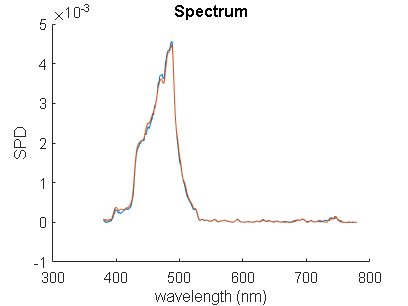

v = vec_b;
s_predicted = ols.FWD_vec2spdC(v);
ol.setColumn1024Gamma(v)
mea = cs.measure;
clf
hold on
s_predicted.plot
mea.plot

% NEC PA271 AdobeRGB mode

disp = NECPA271Sim;

vec_r = ols.INV_spec2vec(disp.spec_r);

ans = 'Solving M * A = B with R...'

ans = 0

ans = 1

R version 4.2.0 (2022-04-22 ucrt) -- "Vigorous Calisthenics"
Copyright (C) 2022 The R Foundation for Statistical Computing
Platform: x86_64-w64-mingw32/x64 (64-bit)

R is free software and comes with ABSOLUTELY NO WARRANTY.
You are welcome to redistribute it under certain conditions.
Type 'license()' or 'licence()' for distribution details.

  Natural language support but running in an English locale

R is a collaborative project with many contributors.
Type 'contributors()' for more information and
'citation()' on how to cite R or R packages in publications.

Type 'demo()' for some demos, 'help()' for on-line help, or
'help.start()' for an HTML browser interface to help.
Type 'q()' to quit R.

[Previously saved workspace restored]

> source("C:/Users/wcc/Documents/GitHub/MIS_acquire/@Rsolver/R_mysolveA1024.R")
> R_mysolveA1024()
Error in t(M) %*% ginv(M %*% t(M)) %*% B : non-conformable arguments
Calls: R_mysolveA1024
Execution halted


Error using csvread
File not found.

Error in Rsolver (line 83)
            A = csvread(filepath_A);

Error in OL490Sim/INV_spdC2vec (line 322)
            rsolve = Rsolver(ref_m,ref_target.amplitude);

Error in 

vec_g = ols.INV_spec2vec(disp.spec_g);
vec_b = ols.INV_spec2vec(disp.spec_b);

save('vec_rift_HIMS1','vec*')